clear all;
clc;
DCDC_param;

%% Simulation Params
Tstep = Tsw*0.5e-2

Tstep = 5.0000e-07

Tsim_OL = 0.2

Tsim_OL = 0.2000


Tsim_inLoop = 0.1

Tsim_inLoop = 0.1000


Tsim_outLoop = 0.4

Tsim_outLoop = 0.4000


s = zpk(0,[],1); %s = wj

## Anti-Aliasing Filter

% 6.6x under 10kHz
% cutoff = 1.5kHz
%
Rf1 = 6.8e3 %Ohm

Rf1 = 6800

Rf2 = 6.8e3 %Ohm

Rf2 = 6800

Rf3 = 4.3e3 %Ohm

Rf3 = 4300

Cf1 = 10e-9; %F
Cf2 = 47e-9; %F

K = -Rf2/Rf1;
a = Rf2*Rf3*Cf1*Cf2;
b = Rf3*Cf1 + Rf2*Cf1 + Rf2*Rf3*Cf1/Rf1;
c = 1;
num_aaf = K;
den_aaf = [a b c];
Gaaf = tf(num_aaf, den_aaf);
BWaaf = bandwidth(Gaaf)/(2*pi)

BWaaf = 1.4522e+03

%bode(Gaaf), grid, legend
%}


% Inductor Current Control
bw = 230 % (Hz) Closed-loop bandwidth

bw = 230

VLlim = 0.6 %V ratio of Vin, inner loop saturation limit

VLlim = 0.6000


% Zero-pole cancellation
%{
kp_i = 2*pi*bw*L;
ki_i = 2*pi*bw*R_L; % zero-pole cancellation - (maybe poor distrubance rejection)
%}

% PI 
%
% transient performance
% Maximum overshoot (neglecting zero - might require prefilter)
OS = 0.14 % overshoot

OS = 0.1400

zeta = sqrt((log(OS)^2) /(pi^2 + log(OS)^2))

zeta = 0.5305

wn = 2*pi*bw / sqrt(1 - 2*zeta^2 + sqrt(4*zeta^4 - 4*zeta^2 + 2)) %* 0.65

wn = 1.1689e+03

ts_i = -log(0.02*sqrt(1-zeta^2)) / (zeta*wn)

ts_i = 0.0066

% general second order transfer function
% pole = s^2 + 2*wn*zeta*s + wn^2 = s^2 + s*(kp + R)/L + ki/L
kp_i = 2*zeta*wn*L - RserL

kp_i = 2.4002

ki_i = L*wn^2

ki_i = 2.7053e+03


% anti-windup, prefilter
kaw_i = 1/kp_i %ki_i %kp_i/ki_i %1/kp_i %

kaw_i = 0.4166

kpf_i = ki_i/kp_i

kpf_i = 1.1271e+03


% transfer function
Gpf_i = kpf_i/(s + kpf_i) %prefilter

Gpf_i =
 
   1127.1
  --------
  (s+1127)
 
Continuous-time zero/pole/gain model.
Model Properties


Gol_i = (kp_i + ki_i/s) * (1/(L*s + RserL)) %open loop

Gol_i =
 
  1212.2 (s+1127)
  ---------------
     s (s+28)
 
Continuous-time zero/pole/gain model.
Model Properties


Gcl_i = feedback(Gol_i,1) %close loop

Gcl_i =
 
      1212.2 (s+1127)
  ------------------------
  (s^2 + 1240s + 1.366e06)
 
Continuous-time zero/pole/gain model.
Model Properties


Gclaaf_i = feedback(Gol_i,-Gaaf) %close loop with aaf

Gclaaf_i =
 
    1212.2 (s+1127) (s^2 + 1.121e04s + 7.277e07)
  -------------------------------------------------
  (s^2 + 1245s + 1.686e06) (s^2 + 9989s + 5.896e07)
 
Continuous-time zero/pole/gain model.
Model Properties


Gpfcl_i = Gpf_i*Gcl_i %close loop with prefilter

Gpfcl_i =
 
         1.3663e06 (s+1127)
  ---------------------------------
  (s+1127) (s^2 + 1240s + 1.366e06)
 
Continuous-time zero/pole/gain model.
Model Properties


Gpfclaaf_i = Gpf_i*Gclaaf_i % close loop with prefilter & aaf

Gpfclaaf_i =
 
       1.3663e06 (s+1127) (s^2 + 1.121e04s + 7.277e07)
  ----------------------------------------------------------
  (s+1127) (s^2 + 1245s + 1.686e06) (s^2 + 9989s + 5.896e07)
 
Continuous-time zero/pole/gain model.
Model Properties


[num_i,den_i] = tfdata(Gpfclaaf_i, 'v')

num_i = 1.0e+17 *

         0         0    0.0000    0.0000    0.0012    1.1206


den_i = 1.0e+17 *

    0.0000    0.0000    0.0000    0.0000    0.0020    1.1206


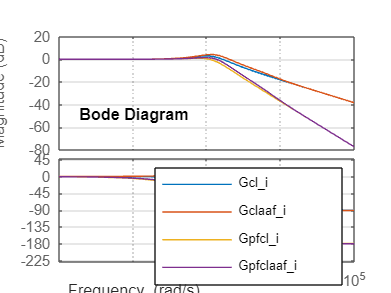


% frequency response
bode(Gcl_i,Gclaaf_i,Gpfcl_i,Gpfclaaf_i), grid, legend

BWcl_i = bandwidth(Gcl_i)/(2*pi)

BWcl_i = 338.9694

BWclaaf_i = bandwidth(Gclaaf_i)/(2*pi)

BWclaaf_i = 413.1163

BWpfcl_i = bandwidth(Gpfcl_i)/(2*pi)

BWpfcl_i = 229.8365

BWpfclaaf_i = bandwidth(Gpfclaaf_i)/(2*pi)

BWpfclaaf_i = 267.7221

%}

%% Capacitor Voltage Control
bw = 35 % (Hz) closed-loop bandwidth

bw = 35

%ResrC = 0; % assume no parasitic series resistance

% transient performance
OS = 0.07 % overshoot

OS = 0.0700

zeta = sqrt((log(OS)^2) /(pi^2 + log(OS)^2))

zeta = 0.6461


% general second order transfer function
% pole = s^2 + 2*wn*zeta*s + wn^2 = s^2 + s*kp/C + ki/C


% PI
% Option 1 - Free selection of parameters
%
wn = 2*pi*bw / sqrt(1 - 2*zeta^2 + sqrt(4*zeta^4 - 4*zeta^2 + 2))

wn = 202.5564

kp_v = 2*zeta*wn*C

kp_v = 0.2617

ki_v = C*wn^2

ki_v = 41.0291

ts_v = -log(0.02*sqrt(1-zeta^2)) / (zeta*wn)

ts_v = 0.0320

%}
% Option 2 - A maximum kp gain is required
%{
kp_v = 2*pi*bw*C; % As taken for P controller or any other value
wn = kp_v / (2*zeta*C); %(rad/s) Natural frequency
ki_v = C*wn^2;
ts_v = -log(0.02*sqrt(1-zeta^2)) / (zeta*wn)
%}

% anti-windup, prefilter
kaw_v = ki_v/kp_v %1/kp_v %kp_v/ki_v %ki_v

kaw_v = 156.7574

kpf_v = ki_v/kp_v

kpf_v = 156.7574


% transfer function
Gpf_v = kpf_v/(s + kpf_v) %kpf_v/((s + kpf_v)*(1 + C*ResrC*s)) %

Gpf_v =
 
   156.76
  ---------
  (s+156.8)
 
Continuous-time zero/pole/gain model.
Model Properties


Gol_v = (kp_v + ki_v/s) * ((1 + C*ResrC*s) / (C*s)) %(1/(C*s)) %

Gol_v =
 
  0.00047113 (s+156.8) (s+5.556e05)
  ---------------------------------
                 s^2
 
Continuous-time zero/pole/gain model.
Model Properties


Goli_v = (kp_v + ki_v/s) * Gpfclaaf_i * ((1 + C*ResrC*s) / (C*s)) %(1/(C*s)) %

Goli_v =
 
  643.71 (s+156.8) (s+1127) (s+5.556e05) (s^2 + 1.121e04s + 7.277e07)
  -------------------------------------------------------------------
    s^2 (s+1127) (s^2 + 1245s + 1.686e06) (s^2 + 9989s + 5.896e07)
 
Continuous-time zero/pole/gain model.
Model Properties


Gcl_v = feedback(Gol_v,1)

Gcl_v =
 
  0.0004709 (s+156.8) (s+5.556e05)
  --------------------------------
     (s^2 + 261.7s + 4.101e04)
 
Continuous-time zero/pole/gain model.
Model Properties


Gcli_v = feedback(Goli_v,1)

Gcli_v =
 
          643.71 (s+5.556e05) (s+1127) (s+156.8) (s^2 + 1.121e04s + 7.277e07)
  -----------------------------------------------------------------------------------
  (s+1127) (s^2 + 289.5s + 5.115e04) (s^2 + 955s + 1.352e06) (s^2 + 9989s + 5.897e07)
 
Continuous-time zero/pole/gain model.
Model Properties


Gpfcl_v = Gpf_v*Gcl_v

Gpfcl_v =
 
    0.073818 (s+156.8) (s+5.556e05)
  -----------------------------------
  (s+156.8) (s^2 + 261.7s + 4.101e04)
 
Continuous-time zero/pole/gain model.
Model Properties


Gpfcli_v = Gpf_v*Gcli_v

Gpfcli_v =
 
             1.0091e05 (s+5.556e05) (s+1127) (s+156.8) (s^2 + 1.121e04s + 7.277e07)
  ---------------------------------------------------------------------------------------------
  (s+156.8) (s+1127) (s^2 + 289.5s + 5.115e04) (s^2 + 955s + 1.352e06) (s^2 + 9989s + 5.897e07)
 
Continuous-time zero/pole/gain model.
Model Properties


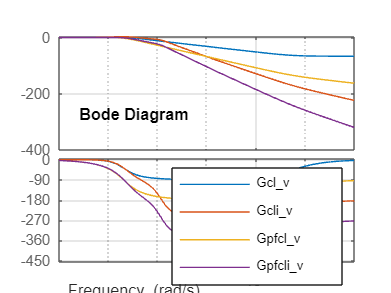


% frequency response
bode(Gcl_v,Gcli_v,Gpfcl_v,Gpfcli_v), grid, legend

BWcl_v = bandwidth(Gcl_v)/(2*pi)

BWcl_v = 63.7664

BWcli_v = bandwidth(Gcli_v)/(2*pi)

BWcli_v = 89.7876

BWpfcl_v = bandwidth(Gpfcl_v)/(2*pi)

BWpfcl_v = 34.9557

BWpfcli_v = bandwidth(Gpfcli_v)/(2*pi)

BWpfcli_v = 40.3497

%}

% stability
%{
G_inOL = Gol_i*Gaaf 
G_outOL = Gol_v*Gpfclaaf_i*Gaaf
margin(G_inOL, 'b'), grid, legend
nyquistplot(G_inOL, 'b'), legend
margin(G_outOL, 'r'), grid, legend
nyquistplot(G_outOL, 'r'), legend
%}